Baseline OFDM Communication System in AWGN Channel

Code for OFDM system has been adopted from: [https://github.com/zhongyuanzhao/dl_ofdm/blob/master/test_v1/OFDM_Benchmark.m](https://github.com/zhongyuanzhao/dl_ofdm/blob/master/test_v1/OFDM_Benchmark.m) 

Step 1: Set up System Parameters 

close all; clear all; clc; 

%System Parameters 
N = 64;                                                 % FFT size, Number of total subcarriers
Ncp = 16;                                               % Length of Cyclic prefix
Ts = 1e-6;                                              % Sampling period of channel
Fd = 0;                                                 % Max Doppler frequency shift
Np = 8;                                                 % No of pilot symbols
Ng = 4;                                                 % No of side guard subcarriers
Ndc = 2;                                                % No of DC guard subcarriers
Ndata = N - Np - 2.*Ng - Ndc;                           % No of Data subcarriers per symbol
Frame_size = 8;                                         % OFDM symbols per frame
Nframes = 2000;                                         % Size of tested OFDM frames: set as 10^4 for smooth curve
M_set = [8, 16];                                        % Modulation orders - 8PSK, 16QAM
SNRs = -10:1:25;                                        % Test SNR points

%Initialize BER Vectors 
ber_all = zeros(3, length(SNRs)); 

%Calculate pilot locations 
DC_sc = [N/2, N/2+1]; %DC guard bands at end 
Effec_sc = Ng+1:N-Ng;
Effec_sc = setdiff(Effec_sc, DC_sc);
pilot_loc = 1:ceil(length(Effec_sc)/Np):length(Effec_sc);
Pilot_sc = Effec_sc(pilot_loc);
guard_sc = [1:Ng,N-Ng+1:N];

Np = length(pilot_loc); %Recalc number of pilot symbols 

%pre-allocate arrays for frames
pilot_sc_frame = [];
guard_sc_frame = [];
DC_sc_frame = [];

for ii = 0:Frame_size-1
    pilot_sc_sym = Effec_sc(sort(mod((pilot_loc + ii*3)-1,length(Effec_sc))+1)); % scattered
    pilot_sc_frame = [pilot_sc_frame, pilot_sc_sym+ii*N];
    guard_sc_frame = [guard_sc_frame, guard_sc+ii*N];
    DC_sc_frame = [DC_sc_frame, DC_sc+ii*N];
end

data_sc_frame = setdiff(1:Frame_size*N,guard_sc_frame);
data_sc_frame = setdiff(data_sc_frame, pilot_sc_frame);
data_sc_frame = setdiff(data_sc_frame, DC_sc_frame);

Step 2: Simulate AWGN Channel for Each Modulation Scheme

%Loop through modulation scheme 
mod_schemes = {'PSK', 'QAM'}; 
for jj = 1:length(mod_schemes)
    M = M_set(jj); %Mod order 
    ber_mod = zeros(1, length(SNRs)); %ber vector all zeros

    for ii = 1:length(SNRs)
        %generate bits
        data_bits = round((M-1)*rand(Ndata*Frame_size,Nframes)); %random integers 
        data_bits_framed = reshape(data_bits, Ndata, Frame_size*Nframes); 
        tx_bits = de2bi(data_bits_framed(:)); % tx bits for error calculation

        %modulate bits 
        if strcmp(mod_schemes(jj),'PSK')
            data_mod = pskmod(data_bits, M, pi/M); %gray coded default
        elseif strcmp(mod_schemes(jj), 'QAM')
            data_mod = qammod(data_bits, M); %gray coded default
        end 
        
        %frame bits 
        Data = zeros(N*Frame_size, Nframes); %guard sc
        Data(data_sc_frame, :) = data_mod; %instert data sc

        txamp = max(abs(data_mod(:)));
        pilot_signal = txamp.*sqrt(1/2).*(1+1i); % Norm pilot power to peak constellation power
        Data(pilot_sc_frame,:)= pilot_signal; % Pilot sc Insertion
        Data = reshape(Data, N, Frame_size*Nframes); %one frame = 8 clmns 
        
        %OFDM Transmitter 
        %To Time Domain via IFFT 
        IFFT_Data = (N/sqrt(N-2*Np))*ifft(Data,N);
        TxCy = [IFFT_Data((N-Ncp+1):N,:); IFFT_Data];       % Add Cyclic prefix
        [r, c] = size(TxCy);
        Tx_Data = TxCy;
        
        %Clip PAPR
        Tx_Amp = abs(Tx_Data);
        Tx_Power = Tx_Amp.^2;
        Power_PAPR8 = 8.*mean(Tx_Power,1);
        Clip_loc = Tx_Power > Power_PAPR8;
        Clip_Data = Tx_Data./Tx_Amp;
        Clip_Data = sqrt(Power_PAPR8).*Clip_Data;
        Tx_Data(Clip_loc) = Clip_Data(Clip_loc);

        %Wireless Channel 
        Tx_Pow_Freq = mean2(abs(Tx_Data).^2);
        Tx_Data = reshape(Tx_Data, r*Frame_size,[]);
        totalFrames = c/Frame_size;
        
        y = awgn(Tx_Data,SNRs(ii),'measured');                            
        y = reshape(y,r,[]);

        %OFDM Receiver
        %remove cyclic prefix
        rx = y(Ncp+1:r,:);  

        %Time domain to frequency domain via FFT 
        rx_freq = (sqrt(N-2*Np)/N)*fft(rx,N,1);

        %reshape 
        FFT_Data = reshape(rx_freq,N*Frame_size,[]);
        
        %extract data
        rx_data = reshape(FFT_Data(data_sc_frame,:), [], Nframes*Frame_size);

        %demodulate bits 
        if strcmp(mod_schemes(jj),'PSK')
            rx_data = pskdemod(rx_data, M, pi/M); %gray coded default
        elseif strcmp(mod_schemes(jj), 'QAM')
            rx_data = qamdemod(rx_data, M); %gray coded default
        end 

        rx_bits = de2bi(rx_data(:));
        [~,errorRate] = biterr(tx_bits, rx_bits);
        ber_mod(ii) = errorRate;
    end

    ber_all(jj+1, :) = ber_mod; %save to large array 
end 

Step 3: Plot BER and Save Results 

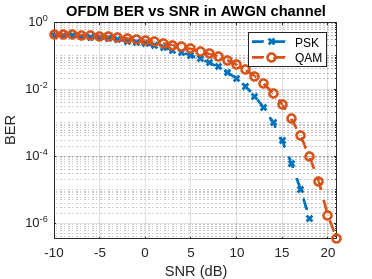

path = '/home/mcash/Desktop/CVNN for CFO and IQI/Results';
cd(path)

mat_name = 'OFDM_AWGN_Baseline.mat';
save(mat_name, 'ber_all');

figure; 
semilogy(SNRs,ber_all(2,:),'--x','LineWidth',2);
hold on 
semilogy(SNRs,ber_all(3,:),'--o','LineWidth',2);
grid on;
title('OFDM BER vs SNR in AWGN channel');
xlabel('SNR (dB)');
ylabel('BER');
legend(mod_schemes);



path = '/home/mcash/Desktop/CVNN for CFO and IQI/Images';
cd(path)
savefig(gcf, 'OFDM_AWGN_Baseline.fig')